Dijkstra Run section

% Maze
createMaze_1;

% run Dijkstra's algorithm
disp("Dijkstra's")

Dijkstra's


pathDijkstra = Dijkstra(Maze);

PushCounter: 3393
PopCounter: 3081


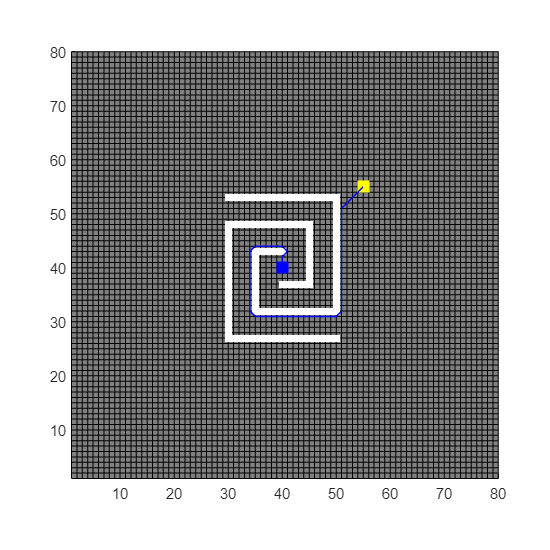


% pltoing the Maze after applying Dijkstra. 
hold on;
plot(pathDijkstra(:, 1), pathDijkstra(:, 2), 'b', 'LineWidth', 1);
hold off;

A* Run section

% Maze
createMaze_1;

% run A* algorithm
disp('A*')

A*


pathAStar = A_Star(Maze);

PushCounter: 686
PopCounter: 514


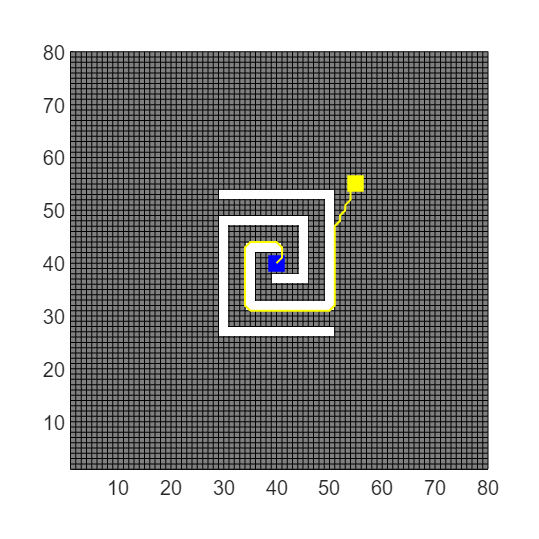


% pltoing the Maze after applying A*. 
hold on;
plot(pathAStar(:, 1), pathAStar(:, 2), 'y', 'LineWidth', 1);
hold off;

function path = Dijkstra(Maze)
    
    map = Maze.map;
    start = Maze.start;
    goal = Maze.goal;
    
    % Initialize data 
    distances = inf(size(map));  % Start distances
    Pointers = zeros(size(map, 1), size(map, 2), 2);  % Pointers to reconstruct the path
    
    % start node values
    distances(start(1), start(2)) = 0;
    
    %  push and pop variabels 
    push = 0;
    pop = 0;
    
    % Dijkstra's algorithm
    while true
        % Find smallest distance path/node
        SmallestDistance = inf;
        currentNode = [];
        for i = 1:size(map, 1)
            for j = 1:size(map, 2)
                if map(i, j) ~= inf && distances(i, j) < SmallestDistance
                    SmallestDistance = distances(i, j);
                    currentNode = [i, j];
                end
            end
        end
        
        if isempty(currentNode)
            % when we find no path
            path = [];
            disp("No path found!");
            disp("PushCounter: " + push);
            disp("PopCounter: " + pop);
            return;
        end
        
        % popcounter
        pop = pop + 1;
        
        % Check if goal node is reached
        if isequal(currentNode, goal)
            % Reconstruct the path from goal to start
            path = regeneratPath(Pointers, currentNode);
            disp("PushCounter: " + push);
            disp("PopCounter: " + pop);
            return;
        end
        
        % Neighboring nodes Update distances 
        neighbors = getNeighbors(currentNode, map);
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i, :);
            distance = distances(currentNode(1), currentNode(2)) + calculateDistance(currentNode, neighbor);
            if distance < distances(neighbor(1), neighbor(2))
                distances(neighbor(1), neighbor(2)) = distance;
                Pointers(neighbor(1), neighbor(2), :) = currentNode;
                
                % pushcounter
                push = push + 1;
            end
        end
        
        % saving that we visited the current node so we do not visit it
        % again. 
        map(currentNode(1), currentNode(2)) = inf;
    end
end

Regenerate Path

function path = regeneratPath(parentPointers, goal)
    % Reconstruct the path from the goal to the start using pointers
    path = [];
    current = goal;
    
    while ~isequal(current, [0, 0])
        path = [current; path];
        current = squeeze(parentPointers(current(1), current(2), :))';
    end
 
end

Distance between two coordinates points

function distance = calculateDistance(position1, position2)
    distanceX = abs(position1(1) - position2(1));
    distanceY = abs(position1(2) - position2(2));
    diagonalCost = sqrt(2);
    straightCost = 1;
    distance = straightCost * (distanceX + distanceY) + (diagonalCost - 2 * straightCost) * min(distanceX, distanceY);
end

A* Algorithm 

function path = A_Star(Maze)
    
    map = Maze.map;
    start = Maze.start;
    goal = Maze.goal;
    
    % Costs 
    diagonalCost = sqrt(2);  % Diagonal Cost
    straightCost = 1;        % Vertical/horizontal Cost
    
    % Initialize 
    PriorityQueue = containers.Map();  % Priority queue 
    Cost_Values = inf(size(map));    % Start cost
    fValues = inf(size(map));    
    Pointers = zeros(size(map, 1), size(map, 2), 2);  %  Pointers to reconstruct the path
    
    % Set initial values for the start node
    Cost_Values(start(1), start(2)) = 0;
    fValues(start(1), start(2)) = heuristic(start, goal);
    PriorityQueue(num2str(start)) = fValues(start(1), start(2));
    
    % push and pop 
    Push = 0;
    Pop = 0;
    
    
    while ~isempty(PriorityQueue)
        % Extract node with the lowest fValue from the PriorityQueue
        keys = PriorityQueue.keys;
        [~, minIdx] = min(cell2mat(PriorityQueue.values));
        currentStr = keys{minIdx};
        current = str2num(currentStr);
        PriorityQueue.remove(currentStr);
        
        % Increment pop counter
        Pop = Pop + 1;
        
        % if we reach the goal
        if isequal(current, goal)
            
            path = regeneratPath(Pointers, current);
            disp("PushCounter: " + Push);
            disp("PopCounter: " + Pop);
            return;
        end
        
        % Neighboring nodes
        neighbors = getNeighbors(current, map);
        
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i,:);
            
            % Calculate the cost from the current node to the neighbor
            if abs(neighbor(1) - current(1)) + abs(neighbor(2) - current(2)) == 2
                
                cost = diagonalCost;
            else
                
                cost = straightCost;
            end
            
            % Calculate cost_value
            new_Cost_Value = Cost_Values(current(1), current(2)) + cost;
           
            if new_Cost_Value < Cost_Values(neighbor(1), neighbor(2))
               
                Cost_Values(neighbor(1), neighbor(2)) = new_Cost_Value;
                fValues(neighbor(1), neighbor(2)) = new_Cost_Value + heuristic(neighbor, goal);
                Pointers(neighbor(1), neighbor(2), :) = current;
                
                PriorityQueue(num2str(neighbor)) = fValues(neighbor(1), neighbor(2));
               
                Push = Push + 1;
            end
        end

    end
    
    % When we do not find the goal
    path = [];
    disp("No path found!");
    disp("PushCounter: " + Push);
    disp("PopCounter: " + Pop);
end

Function Heuristic

function h = heuristic(position, goal)
    % Euclidean distance 
    h = sqrt((position(1) - goal(1))^2 + (position(2) - goal(2))^2);
end

Neighbor Function

function neighbors = getNeighbors(position, map)
      
    % Extract x and y coordinates of the current point
    x = position(1);
    y = position(2);

   
    dx = [-1, -1, 0, 0, 1, 1, -1, 1]; % Displacement in x-direction for each neighbor
    dy = [-1, 0, 1, -1, 0, 1, 1, -1]; % Displacement in y-direction for each neighbor
    
  
    nx = x + dx; % Potential x-coordinates of neighbors
    ny = y + dy; % Potential y-coordinates of neighbors

   % Identify indices of neighbors within map boundaries and not obstacles
    valid_indices = nx >= 1 & nx <= size(map, 1) & ny >= 1 & ny <= size(map, 2) & map(nx + (ny - 1) * size(map, 1)) ~= inf;
    
    neighbors = [nx(valid_indices)', ny(valid_indices)']; % Store valid neighbor coordinates in a matrix
end